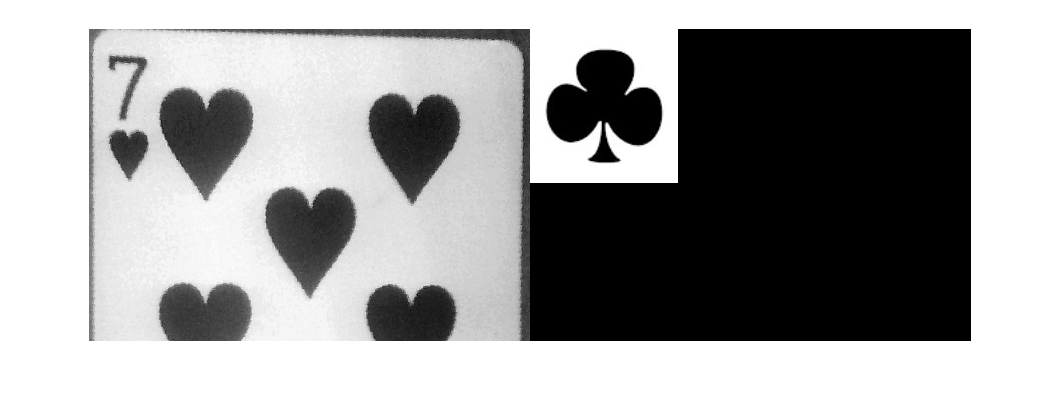

%load cropped2 
cropped2 = rgb2gray(imread('V:\Datasets\Card Suits\Clubs\7.jpg'));
imshowpair(R,cropped2,'montage');

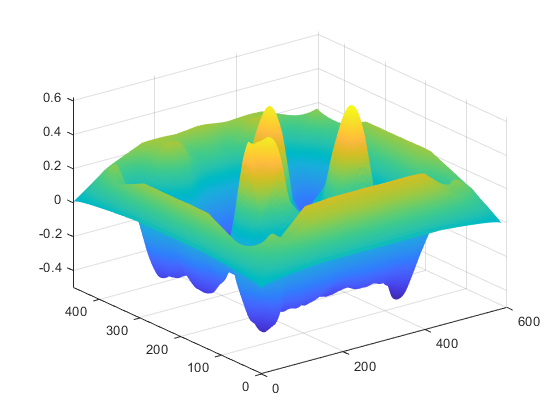

c = normxcorr2(cropped2,R);
figure, surf(c), shading flat

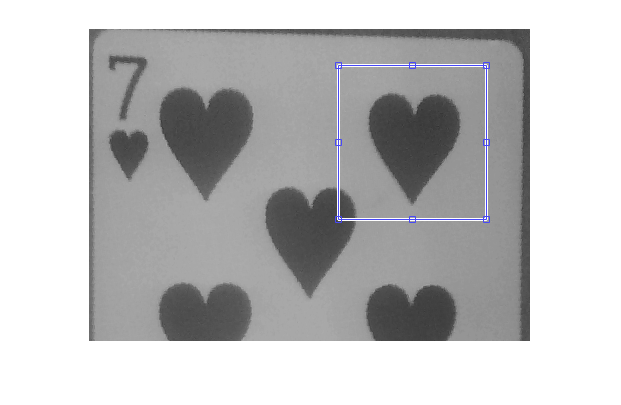

[ypeak, xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(cropped2,2);
xoffSet = xpeak-size(cropped2,1);
figure
imshow(R);
imrect(gca, [xoffSet+1, yoffSet+1, size(cropped2,2), size(cropped2,1)]);